clear
clc
close all

%% Change directory
% Get the full path of the currently running script
if isdeployed
    % If the code is deployed, use the built-in method
    scriptFullPath = mfilename('fullpath');
else
    % If running in the MATLAB environment, use the editor API
    scriptFullPath = matlab.desktop.editor.getActiveFilename;
end

% Extract the directory part of the path
[scriptDir, ~, ~] = fileparts(scriptFullPath);

% Change the current directory to the script's directory
cd(scriptDir);

% Display the current directory to confirm the change
disp(['Current directory changed to: ', scriptDir]);

Current directory changed to: C:\Users\giaco\Git_Repositories\Semester_Thesis_1\Data\Heat Pump


data25 = readtable('Data/Heat Pump/temperature25.xlsx');
data50 = readtable('Data/Heat Pump/temperature50.xlsx');
data75 = readtable('Data/Heat Pump/temperature75.xlsx');

data = vertcat(data25, data50, data75);

data_max.I_max = 6.6;
data_max.U_max = 9.1;
data_max.Qremoved_max = 34;
data_max.DeltaT_max = NaN;

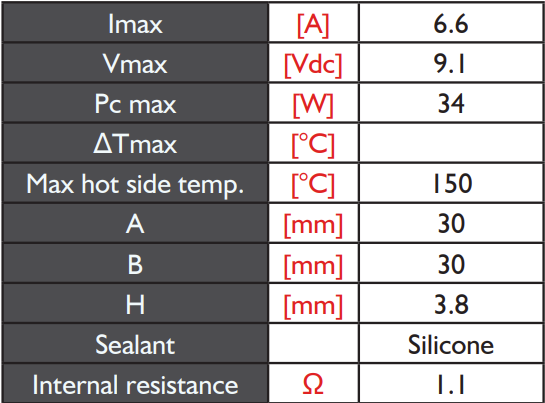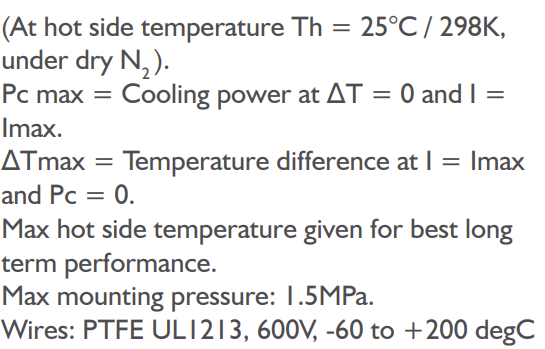

# Plot

curr    = linspace(1,6,6);      %A
deltaT  = linspace(0,60,7);     %°C
T_hot   = linspace(25,75,3);    %°C

curr_str    = string(curr);
deltaT_str  = string(deltaT);
T_hot_str   = string(T_hot);

curr_len    = length(curr_str);
deltaT_len  = length(deltaT_str);
T_hot_len   = length(T_hot_str);

curr_colormap   = flipud(winter(curr_len));
deltaT_colormap = flipud(autumn(deltaT_len));
T_hot_colormap  = flipud(autumn(T_hot_len));

% Electrical power
label_P_el = "Electrical power / W";

% Dictionary for the labels
headers_keys = data.Properties.VariableNames;
label_values = ["Hot side temperature / °C", ...
                "Input voltage / V", ...
                "Temperature difference / °C", ...
                "Current / A", ...
                "Heat from cold side / W", ...
                "Heat to hot side / W", ...
                "Coefficient of performance COP / -"];
label_dict = containers.Map(headers_keys, label_values);

% Dictionary for the legends
headers_keys = data.Properties.VariableNames;
legend_values = ["T_h = ", ...
                 "U = ", ...
                 "\Delta_T = ", ...
                 "I = ", ...
                 "Q_{in} = ", ...
                 "Q_{out}", ...
                 "COP = "];
legend_dict = containers.Map(headers_keys, legend_values);

% Dictionary for the units
headers_keys = data.Properties.VariableNames;
units_values = ["°C", ...
                "V", ...
                "°C", ...
                "A", ...
                "W", ...
                "W", ...
                ""];
units_dict = containers.Map(headers_keys, units_values);

# Delta T_max Estimation

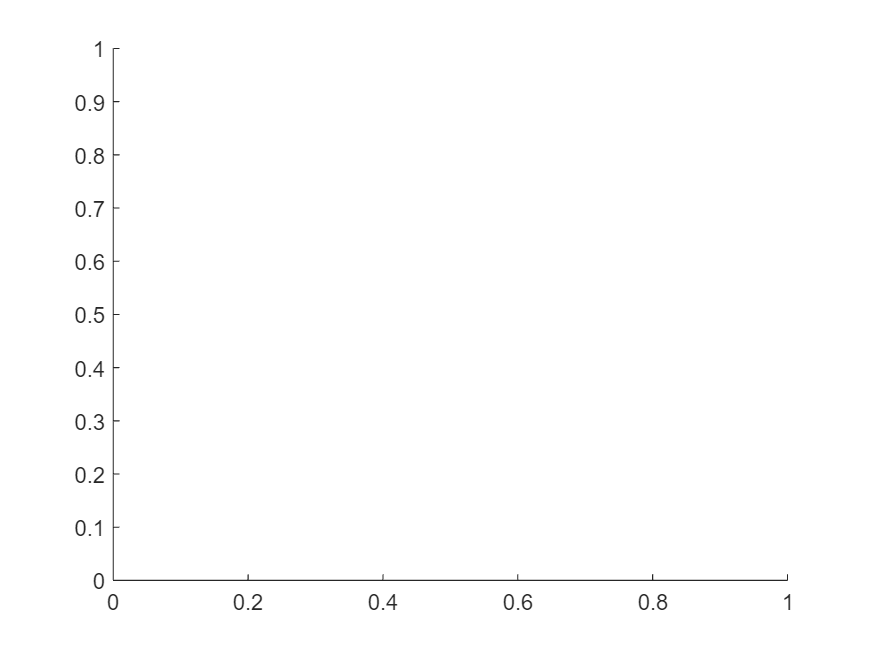

figure
hold on


x2plot = linspace(71,73,21)';

xpred = [repmat(data_max.I_max, length(x2plot), 1), ...     %x1 = current
         x2plot, ...                                        %x2 = delta T
         repmat(T_hot(1), length(x2plot), 1)];              %x3 = T hot side
ypred = predict(mdl_Q_removed, xpred);

Unrecognized function or variable 'mdl_Q_removed'.


p_pred = plot(x2plot, ypred);
p_pred.HandleVisibility = 'off';
p_pred.LineStyle = '-';
p_pred.Color = 'r';

% Define a function handle for the prediction
fun = @(x) predict(mdl_Q_removed, [repmat(data_max.I_max, length(x), 1), x, repmat(T_hot(1), length(x), 1)]);

% Find the zero around x = 72
x_zero = fzero(@(x) fun(x), 72);
fprintf('DeltaT_max = %.4f\n', x_zero);
data_max.DeltaT_max = x_zero;
xline(x_zero)

xlabel(label_dict(headers_keys{3}));
ylabel(label_dict(headers_keys{5}));
grid on
box on

hold off